close all
clear all
clc

%% Import dati
opts=detectImportOptions('./data/MiniProjectEFSA.xlsx');
warning('OFF', 'MATLAB:table:ModifiedAndSavedVarnames')
data=readtable('./data/MiniProjectEFSA.xlsx', opts);
data.Properties.VariableNames={'response','numberOfAnimals','SD','dose','sex','endpoint'};

%% Subset Selection - endpoint 1
data_endpoint_1=data(data.endpoint==1,:);
gender_female_1 = categorical(data_endpoint_1.sex);
dose_1 = data_endpoint_1.dose;
nOa_1= data_endpoint_1.numberOfAnimals;
response_1=data_endpoint_1.response;

weights_1= 1./(data_endpoint_1.SD.^2);

tbl1=table(response_1,nOa_1,dose_1,gender_female_1);

mdl_1 = stepwiselm(tbl1,'ResponseVar','response_1','Weights',weights_1,'Verbose',2)

   Change in AdjRsquared for adding nOa_1 is 0.23537
   Change in AdjRsquared for adding dose_1 is -0.1558
   Change in AdjRsquared for adding gender_female_1 is 0.94992
1. Adding gender_female_1, AdjRsquared = 0.94992
   Change in AdjRsquared for adding nOa_1 is 0.0018494
   Change in AdjRsquared for adding dose_1 is 0.030001
2. Adding dose_1, AdjRsquared = 0.97992
   Change in AdjRsquared for adding nOa_1 is -0.001954
   Change in AdjRsquared for adding dose_1:gender_female_1 is 0.0037649
3. Adding dose_1:gender_female_1, AdjRsquared = 0.98369
   Change in AdjRsquared for adding nOa_1 is -0.0051986
   No candidate terms to remove


mdl_1 = Linear regression model:
    response_1 ~ 1 + dose_1*gender_female_1

Estimated Coefficients:
                                Estimate      SE        tStat       pValue  
                                ________    _______    _______    __________

    (Intercept)                   567.56     16.152     35.138    3.9149e-06
    dose_1                      -0.50922    0.15859    -3.2109      0.032561
    gender_female_1_1            -243.86     18.777    -12.987    0.00020282
    dose_1:gender_female_1_1     0.28413     0.1936     1.4676       0.21611


Number of observations: 8, Error degrees of freedom: 4
Root Mean Squared Error: 0.361
R-squared: 0.991,  Adjusted R-Squared: 0.984
F-statistic vs. constant model: 142, p-value = 0.000162

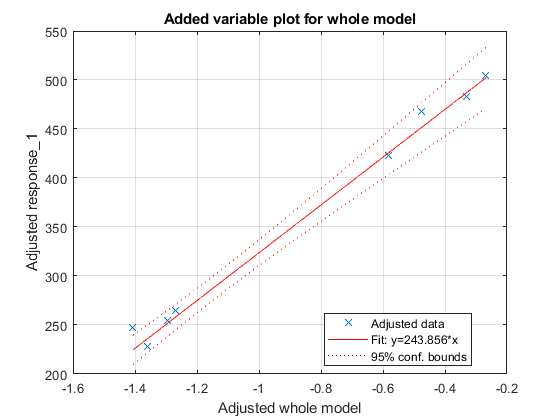


plot(mdl_1)
grid on

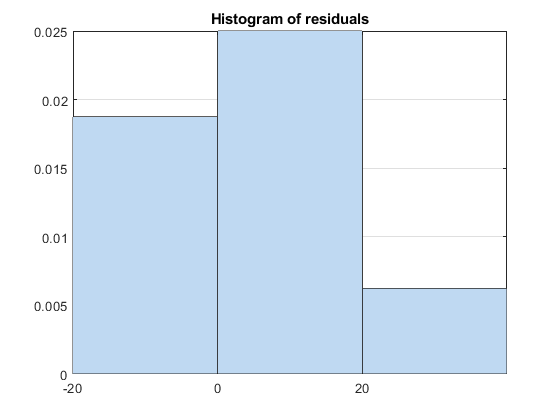

plotResiduals(mdl_1)
grid on

anova(mdl_1)

ans = 4×5 table
                               SumSq     DF    MeanSq       F         pValue  
                              _______    __    _______    ______    __________

    dose_1                     1.5968    1      1.5968    12.265      0.024847
    gender_female_1            54.543    1      54.543    418.96    3.3646e-05
    dose_1:gender_female_1    0.28042    1     0.28042     2.154       0.21611
    Error                     0.52075    4     0.13019                        


coefCI(mdl_1)

ans =   522.7105  612.4032
   -0.9495   -0.0689
 -295.9875 -191.7234
   -0.2534    0.8216


%% Subset Selection - endpoint 2
data_endpoint_2=data(data.endpoint==2,:);
gender_female_2 = categorical(data_endpoint_2.sex);
dose_2 = data_endpoint_2.dose;
nOa_2= data_endpoint_2.numberOfAnimals;
response_2=data_endpoint_2.response;

weights_2= 1./(data_endpoint_2.SD.^2);

tbl2=table(response_2,nOa_2,dose_2,gender_female_2);

mdl_2 = stepwiselm(tbl2,'ResponseVar','response_2','Weights',weights_2,'Verbose',2)

   pValue for adding nOa_2 is 0.52001
   pValue for adding dose_2 is 0.0027102
   pValue for adding gender_female_2 is 0.32633
1. Adding dose_2, FStat = 24.0125, pValue = 0.0027102
   pValue for adding nOa_2 is 0.19981
   pValue for adding gender_female_2 is 0.12586
   No candidate terms to remove


mdl_2 = Linear regression model:
    response_2 ~ 1 + dose_2

Estimated Coefficients:
                   Estimate        SE         tStat      pValue  
                   _________    _________    _______    _________

    (Intercept)       44.794      0.35665      125.6    1.718e-11
    dose_2         -0.018673    0.0038106    -4.9003    0.0027102


Number of observations: 8, Error degrees of freedom: 6
Root Mean Squared Error: 0.44
R-squared: 0.8,  Adjusted R-Squared: 0.767
F-statistic vs. constant model: 24, p-value = 0.00271

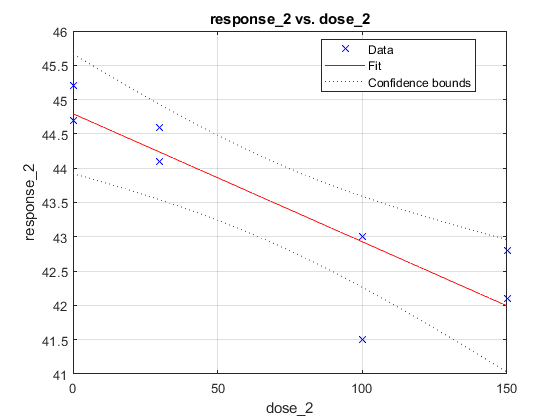


plot(mdl_2)
grid on

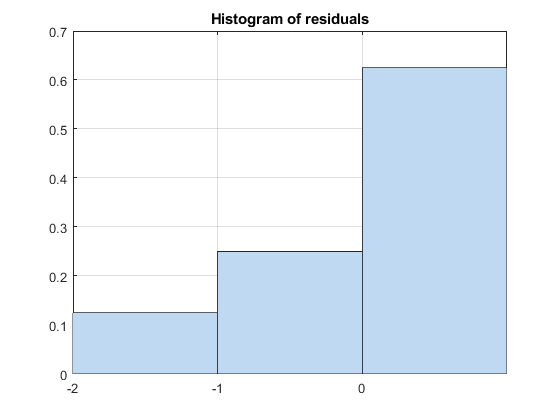

plotResiduals(mdl_2)
grid on

anova(mdl_2)

ans = 2×5 table
              SumSq     DF    MeanSq       F        pValue  
              ______    __    _______    ______    _________

    dose_2    4.6449    1      4.6449    24.012    0.0027102
    Error     1.1606    6     0.19344                       


coefCI(mdl_2)

ans =    43.9215   45.6669
   -0.0280   -0.0093


%% Subset Selection - endpoint 3
data_endpoint_3=data(data.endpoint==3,:);
gender_female_3 = categorical(data_endpoint_3.sex);
dose_3 = data_endpoint_3.dose;
nOa_3= data_endpoint_3.numberOfAnimals;
response_3=data_endpoint_3.response;

weights_3= 1./(data_endpoint_3.SD.^2);

tbl3=table(response_3,nOa_3,dose_3,gender_female_3);

mdl_3 = stepwiselm(tbl3,'ResponseVar','response_3','Weights',weights_3,'Verbose',2)

   pValue for adding nOa_3 is 0.66349
   pValue for adding dose_3 is 0.021132
   pValue for adding gender_female_3 is 0.16835
1. Adding dose_3, FStat = 9.6065, pValue = 0.021132
   pValue for adding nOa_3 is 0.3046
   pValue for adding gender_female_3 is 0.00052989
2. Adding gender_female_3, FStat = 62.0532, pValue = 0.000529891
   pValue for adding nOa_3 is 0.44429
   pValue for adding dose_3:gender_female_3 is 0.45223
   pValue for removing dose_3 is 0.00011295


mdl_3 = Linear regression model:
    response_3 ~ 1 + dose_3 + gender_female_3

Estimated Coefficients:
                         Estimate        SE         tStat       pValue  
                         _________    _________    _______    __________

    (Intercept)             18.223      0.12314     147.99    2.6726e-10
    dose_3               -0.013876    0.0012731    -10.899    0.00011295
    gender_female_3_1       1.0833      0.13752     7.8774    0.00052989


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 0.367
R-squared: 0.971,  Adjusted R-Squared: 0.96
F-statistic vs. constant model: 84.7, p-value = 0.000139

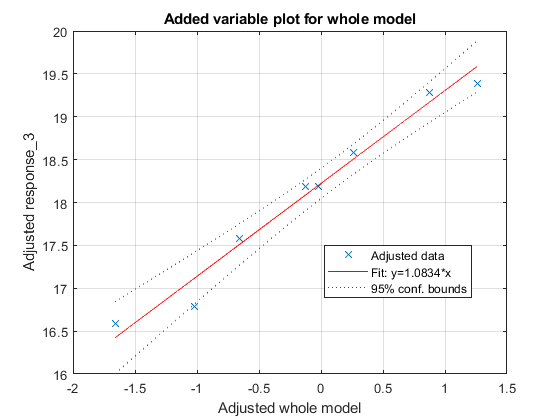


plot(mdl_3)
grid on

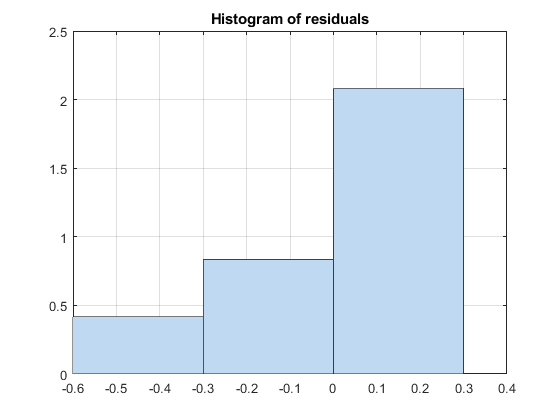

plotResiduals(mdl_3)
grid on

anova(mdl_3)

ans = 3×5 table
                        SumSq     DF    MeanSq       F         pValue  
                       _______    __    _______    ______    __________

    dose_3              15.993    1      15.993     118.8    0.00011295
    gender_female_3     8.3537    1      8.3537    62.053    0.00052989
    Error              0.67311    5     0.13462                        


coefCI(mdl_3)

ans =    17.9062   18.5393
   -0.0171   -0.0106
    0.7298    1.4368
